#     ***Institute of Robotics, University of Innopolis***

# Dynamics of Nonlinear Robotic Systems

# Homework 5

## By Amer Al Badr

October 25,2020

## Task One & Two

First, We find the Forward kinematics for the centers of mass in our RP robot,

then we calculate the Jacobian matrices associated with the centers of mass by means of Skew theory in order to obtain the angular and linear velocities for each joint.

After that, we calculate the kinetic and potential energy and apply them in Euler-Lagrange equation.

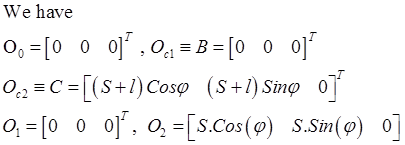

Now we calculate the Jacobians  matrices associated with the centers of mass by means of Skew theory:

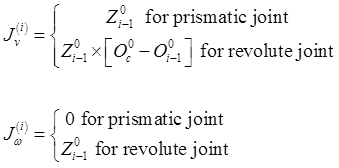

Then we obtain:

(first joint is revolute)

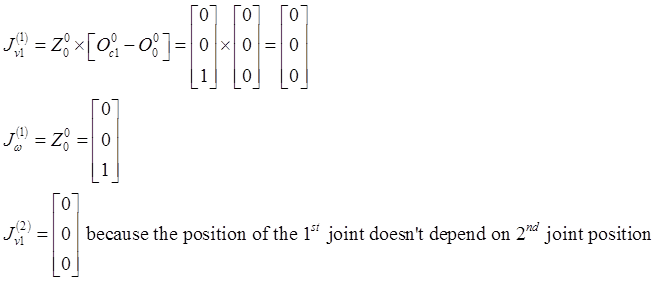

Second joint is prismatic:

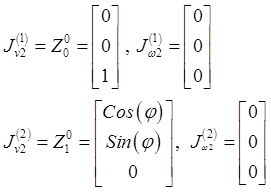

Now we calculate the Kinetic Energy from the following equation:

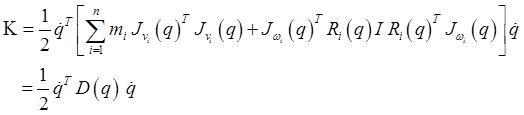

Where D(q) is the inertia matrix for the whole robot.

Now we code what have been mentioned:

clear all
syms q1 q2 dq1 dq2 ddq1 ddq2 l m1 m2 I1 I2 g real

q1=phi         q2=S

Skew Theory

Getting the centers of mass and orgins FK

O0=[0 0 0]'

O0 =      0
     0
     0


O1=[0 0 0]'

O1 =      0
     0
     0


O2=[q2*cos(q1) q2*sin(q1) 0]'

$$O2 = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

B=[0 0 0]'

B =      0
     0
     0


C=[(q2+l)*cos(q1), (q2+l)*sin(q1),0]'

$$C = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(l+q_{2}\right)\\ 0 \end{array}\right)$$

Now we get Z:

Z0=[0 0 1]'

Z0 =      0
     0
     1


Z1=[cos(q1),sin(q1),0]'

$$Z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

Calculate Jacobians

Zer=[0 0 0]';
Jv1=[cross(Z0,(B-O0)),Zer]

Jv1 =      0     0
     0     0
     0     0


Jv2=[Z0,Z1]

$$Jv2 = \left(\begin{array}{cc} 0 & \cos\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right)\\ 1 & 0 \end{array}\right)$$

Jw1=[Z0,Zer]

Jw1 =      0     0
     0     0
     1     0


Jw2=[Zer,Zer];%Prismatic Joint

Now we calculate Kinetic Energy

R1=Rz(q1);
R1=R1(1:3,1:3)

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2=R1

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


q=[q1,q2]';
D1=m1*(Jv1)'*Jv1+Jw1'*R1*I1*R1'*Jw1

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2=m2*(Jv2)'*Jv2+Jw2'*R2*I2*R2'*Jw2

$$D2 = \left(\begin{array}{cc} m_{2} & 0\\ 0 & m_{2}\,{\cos\left(q_{1}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2} \end{array}\right)$$

D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} I_{1}+m_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

Now we calculate the Potential energy

then we obtain G matrix by taking the derivitive of the potential energy

P1 = 0;
P2 = m2*g*(q2+l)*sin(q1);
P = P1+P2;
G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)$$

G2=diff(P,q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$

G=[G1;G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

Now we calculate Coriolis matrix from the elements of D matrix

dq=[dq1;dq2];
ddq=[ddq1;ddq2];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

We finally obtain Euler-Lagrange motion equation as follows:

torque = D*ddq+C*dq+G

$$torque = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(I_{1}+m_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ {\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

## Task three

D(q1,q2) = subs(D,{m1, m2,l, I1,I2,g},{2 2 0.2 1 2 9.81});
C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2,l, I1,I2,g},{2 2 0.2 1 2 9.81});
G(q1,q2) = subs(G ,{m1, m2,l, I1,I2,g},{2 2 0.2 1 2 9.81});
D(0,0)

$$ans = \left(\begin{array}{cc} 3 & 0\\ 0 & 2 \end{array}\right)$$

C(0,0,0,0)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

G(0,0)

$$ans = \left(\begin{array}{c} \frac{981}{250}\\ 0 \end{array}\right)$$

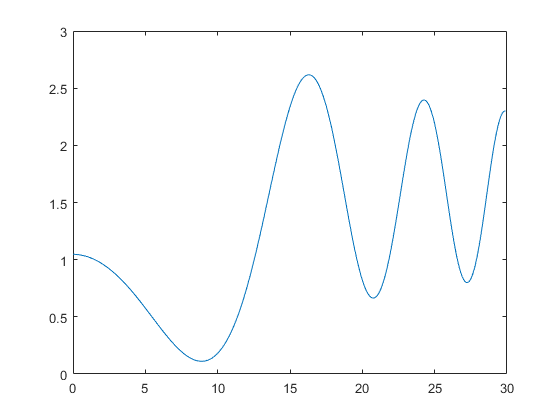

q1_0 = pi/3;
q2_0 = 1;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
%Applying torque
U = [0;0];
n=300;
for i = 1:n
q1p(i)=q1_0;
q2p(i)=q2_0;
dq1p(i)=dq1_0;
dq2p(i)=dq2_0;
ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
dq1_0=dq1p(i) + double(ddq(1)*dt);
dq2_0=dq2p(i) + double(ddq(2)*dt);
q1_0 = q1p(i) + dq1_0*dt;
q2_0 = q2p(i) + dq2_0*dt;
end
t = 0:0.1:(0.1*(n-1));
plot(t,q1p)

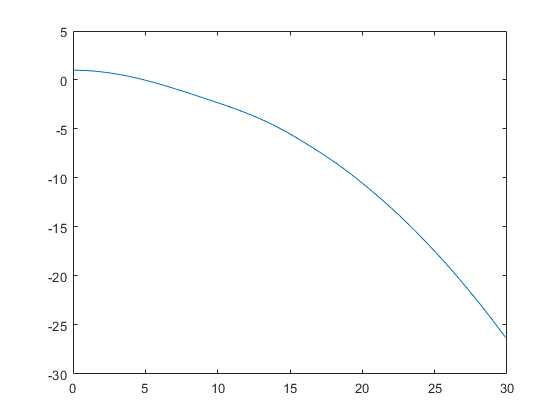

plot(t,q2p)